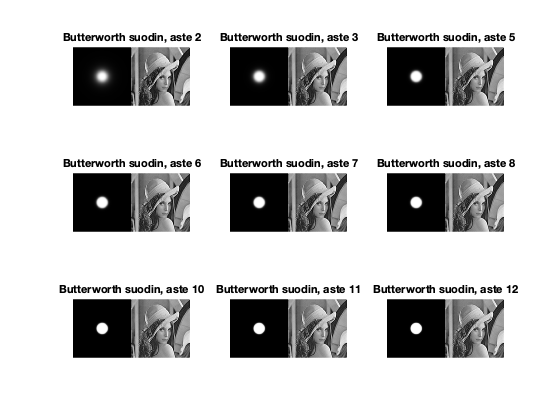

n = [2 3 5 6 7 8 10 11 12];
Do = [10 20 30 40 50 60 70 80 90];

kuva = imread("noisylena.tiff");
sx = size(kuva,2)/2;
sy = size(kuva,1)/2;
x = -(sx-1):sx;
y = -(sy-1):sy;
[X,Y] = meshgrid(x,y);
D = sqrt(X.^2+Y.^2);

H_ideal = D<=50;

I = imread("noisylena.tiff");
figure
for i=1:max(size(n))
    I_DFT = fft2(I);
    I_DFTshift = fftshift(I_DFT);
    H_Butter = 1./(1+(D/50).^(2*n(i)));
    HI = H_Butter.*I_DFTshift;
    I_DFT = ifftshift(HI);
    I_IDFT = ifft2(I_DFT);
    I_new = uint8(real(I_IDFT));
    subplot(3, 3, i)
    imshowpair(H_Butter, I_new, 'montage')
    str = ("Butterworth suodin, aste " + n(i));
    title(str)
end

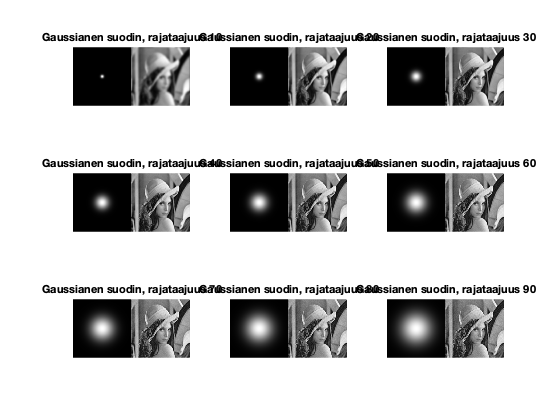


figure
for i=1:max(size(Do))
    I_DFT = fft2(I);
    I_DFTshift = fftshift(I_DFT);
    H_Gaussian = exp(-D.^2 /(2*Do(i)^2));
    HI = H_Gaussian.*I_DFTshift;
    I_DFT = ifftshift(HI);
    I_IDFT = ifft2(I_DFT);
    I_new = uint8(real(I_IDFT));
    subplot(3, 3, i)
    imshowpair(H_Gaussian, I_new, 'montage')
    str = ("Gaussianen suodin, rajataajuus " + Do(i));
    title(str)
end

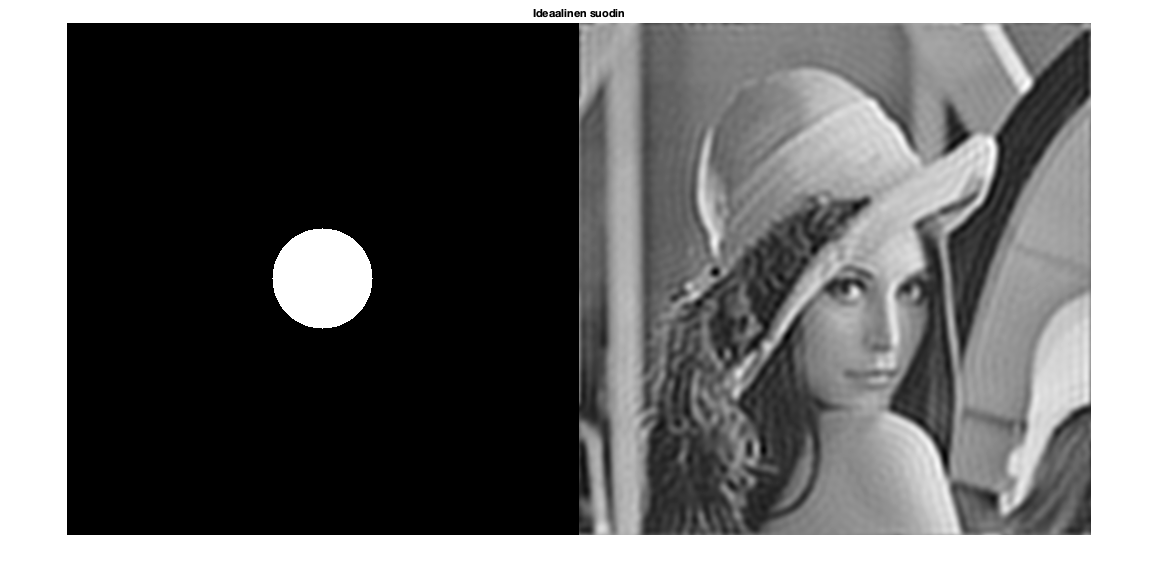


figure
I_DFT = fft2(I);
I_DFTshift = fftshift(I_DFT);
HI = H_ideal.*I_DFTshift;
I_DFT = ifftshift(HI);
I_IDFT = ifft2(I_DFT);
I_new = uint8(real(I_IDFT));
imshowpair(H_ideal, I_new, 'montage')
title('Ideaalinen suodin')

Ideaalisuotimen raja on selkeä, se ei päästä arvoja tietyn arvon jälkeen. Kuvassa voidaan huomata ideaalisuotimelle tyypillistä rengastumista.

Butterworth suotimessa huomataan, että asteen kasvaessa päästettävät taajuudet eivät muutu kauheasti, mutta raja tarkentuu ja se alkaa muistuttaa ideaalisuodinta. 

Gaussinen suodatin päästää sitä enemmän taajuuksia, mitä suurempi rajataajuus. Alussa raja-taajuuden ollessa todella pieni, taajuus oli todella kapea ja tästä syystä kuva on todella sumea. Taajuuden kasvaessa kuva alkaa näyttää paremmalta. Gaussisessa suodattimessa kuvien eron näki parhaiten. Kuvat ei kuitenkaan yhtä pehmeitä kuin Butterworthissa.